# Homework 3

## Problem 1 (6c, 8c)

clear; clc;

syms x

x_vec = [0.1, 0.2, 0.3, 0.4];
f_vec = [-0.29004986, -0.56079734, -0.81401972, -1.0526302];

P_1(x) = LagrangePolynomial(f_vec(1:2), x_vec(1:2));
vpa(simplify(P_1(x)), 4)

$$ans = -2.7075\,x-0.0193$$

vpa(P_1(0.18), 5)

$$ans = -0.5066$$


P_2(x) = LagrangePolynomial(f_vec(1:3), x_vec(1:3));
vpa(simplify(P_2(x)), 4)

$$ans = 0.8763\,x^{2}-2.9704\,x-0.0018$$

vpa(P_2(0.18), 5)

$$ans = -0.5080$$


P_3(x) = LagrangePolynomial(f_vec, x_vec);
vpa(simplify(P_3(x)), 4)

$$ans = -0.4855\,x^{3}+1.1676\,x^{2}-3.0238\,x+0.0011$$

vpa(P_3(0.18), 5)

$$ans = -0.5081$$


f(x)= x^2*cos(x)-3*x

$$f(x) = x^{2}\,\cos\left(x\right)-3\,x$$

vpa(f(0.18), 5)

$$ans = -0.5081$$

f_diff_2(x) = diff(f, x, 2)

$$f\_diff\_2(x) = 2\,\cos\left(x\right)-x^{2}\,\cos\left(x\right)-4\,x\,\sin\left(x\right)$$

f_diff_3(x) = diff(f, x, 3)

$$f\_diff\_3(x) = x^{2}\,\sin\left(x\right)-6\,\sin\left(x\right)-6\,x\,\cos\left(x\right)$$


vpa(f_diff_2(0.1), 5)

$$ans = 1.9401$$

vpa(f_diff_3(0.3), 5)

$$ans = -3.4661$$


error_1(x) = f_diff_2(0.1)/factorial(2)*(x - x_vec(1))*(x - x_vec(2));
max_x_1 = vpasolve(diff(error_1) == 0)

$$max\_x\_1 = 0.1500$$

vpa(error_1(max_x_1), 5)

$$ans = -0.0024$$


error_2(x) = f_diff_3(0.3)/factorial(3)*(x - x_vec(1))*(x - x_vec(2))*(x - x_vec(3));
max_x_2 = vpasolve(diff(error_2) == 0)

$$max\_x\_2 = \left(\begin{array}{c} 0.1423\\ 0.2577 \end{array}\right)$$

vpa(error_2(max_x_2), 5)

$$ans = \left(\begin{array}{c} -2.2235e-04\\ 2.2235e-04 \end{array}\right)$$


error_1_act = vpa(abs(f(0.18) - P_1(0.18))/f(0.18), 5)

$$error\_1\_act = -0.0029$$

error_1_act = vpa(abs(f(0.18) - P_2(0.18))/f(0.18), 5)

$$error\_1\_act = -1.4487e-04$$

## Problem 2 (20)

clear; clc;

syms x

x_vec = [0 6 10 13 17 20 28];
f_vec1 = [6.67 17.33 42.67 37.33 30.10 29.31 28.74];
f_vec2 = [6.67 16.11 18.89 15.00 10.56 9.44 8.89];

P_1(x) = LagrangePolynomial(f_vec1, x_vec);
vpa(simplify(P_1(x)), 4)

$$ans = 4.0946e-05\,x^{6}-0.0037\,x^{5}+0.1269\,x^{4}-2.0946\,x^{3}+16.1427\,x^{2}-42.6435\,x+6.6700$$


P_2(x) = LagrangePolynomial(f_vec2, x_vec);
vpa(simplify(P_2(x)), 4)

$$ans = 8.3616e-06\,x^{6}-7.5255e-04\,x^{5}+0.0258\,x^{4}-0.4138\,x^{3}+2.9128\,x^{2}-5.6782\,x+6.6700$$


x_pot_1 = vpasolve(diff(P_1) == 0, [0 28])

$$x\_pot\_1 = \left(\begin{array}{c} 1.9558\\ 10.1885\\ 25.9642 \end{array}\right)$$

x_pot_2 = vpasolve(diff(P_2) == 0, [0 28])

$$x\_pot\_2 = \left(\begin{array}{c} 1.2956\\ 8.7695\\ 26.0438 \end{array}\right)$$


P_1(x_pot_1)

$$ans = \left(\begin{array}{c} -28.9002\\ 42.7084\\ 10.5623 \end{array}\right)$$

P_2(x_pot_2)

$$ans = \left(\begin{array}{c} 3.3729\\ 19.4158\\ 5.7607 \end{array}\right)$$

## Problem 3 (2c)

clear; clc;

x = 0.18;
x_vec = [0.1 0.2 0.3 0.4];
f_vec = [-0.29004986, -0.56079734, -0.81401972, -1.0526302];

Q_1 = NevilleMethod(x, f_vec(1:2), x_vec(1:2));
vpa(Q_1, 5)

$$ans = \left(\begin{array}{ccc} 0.1000 & -0.2900 & 0\\ 0.2000 & -0.5608 & -0.5066 \end{array}\right)$$


Q_2 = NevilleMethod(x, f_vec(1:3), x_vec(1:3));
vpa(Q_2, 5)

$$ans = \left(\begin{array}{cccc} 0.1000 & -0.2900 & 0 & 0\\ 0.2000 & -0.5608 & -0.5066 & 0\\ 0.3000 & -0.8140 & -0.5102 & -0.5080 \end{array}\right)$$


Q_3 = NevilleMethod(x, f_vec, x_vec);
vpa(Q_3, 5)

$$ans = \left(\begin{array}{ccccc} 0.1000 & -0.2900 & 0 & 0 & 0\\ 0.2000 & -0.5608 & -0.5066 & 0 & 0\\ 0.3000 & -0.8140 & -0.5102 & -0.5080 & 0\\ 0.4000 & -1.0526 & -0.5277 & -0.5084 & -0.5081 \end{array}\right)$$

## Problem 4 (10)

clear; clc;

x = 0;
x_vec = [-2 -1 1 2];
f_vec_wrong = [0 0 0 0];
f_vec_right = f_vec_wrong + [0 -2 3 0];

Q_wrong = NevilleMethod(x, f_vec_wrong, x_vec)

Q_wrong =     -2     0     0     0     0
    -1     0     0     0     0
     1     0     0     0     0
     2     0     0     0     0


Q_right = NevilleMethod(x, f_vec_right, x_vec)

Q_right =    -2.0000         0         0         0         0
   -1.0000   -2.0000   -4.0000         0         0
    1.0000    3.0000    0.5000   -1.0000         0
    2.0000         0    6.0000    2.3333    0.6667


## Problem 5 (18)

clear; clc;

syms x

x_vec = [0.25 0.5 1 1.25];
f_vec = [25.2 49.2 60+36.4 60+59.4];

F = vpa(sym(dividedDifference(f_vec, x_vec)), 5)

$$F = \left(\begin{array}{cccc} 25.2000 & 0 & 0 & 0\\ 49.2000 & 96 & 0 & 0\\ 96.4000 & 94.4000 & -2.1333 & 0\\ 119.4000 & 92 & -3.2000 & -1.0667 \end{array}\right)$$


P(x) = F(1,1) + F(2,2)*(x - x_vec(1)) + F(3,3)*(x - x_vec(1))*(x - x_vec(2)) +...
    F(4,4)*(x - x_vec(1))*(x - x_vec(2))*(x - x_vec(3));

vpa(simplify(P), 5)

$$ans(x) = -1.0667\,x^{3}-0.2667\,x^{2}+96.6667\,x+1.0667$$

P(0.75)

$$ans = 72.9667$$

error = abs(73-P(0.75))/73

$$error = 4.5662e-04$$

## Problem 6 (9)

clear; clc;

syms x

x_vec = [0 3 5 8 13]

x_vec =      0     3     5     8    13


f_vec = [0 225 383 623 993]

f_vec =      0   225   383   623   993


f_diff_vec = [75 77 80 74 72]

f_diff_vec =     75    77    80    74    72



F = vpa(sym(HermiteMethod(f_diff_vec, f_vec, x_vec)), 4)

$$F = \left(\begin{array}{ccccccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 75 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 3 & 225 & 75 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 3 & 225 & 77 & 0.6667 & 0.2222 & 0 & 0 & 0 & 0 & 0 & 0\\ 5 & 383 & 79 & 1 & 0.0667 & -0.0311 & 0 & 0 & 0 & 0 & 0\\ 5 & 383 & 80 & 0.5000 & -0.2500 & -0.0633 & -0.0064 & 0 & 0 & 0 & 0\\ 8 & 623 & 80 & 0 & -0.1000 & 0.0300 & 0.0117 & 0.0023 & 0 & 0 & 0\\ 8 & 623 & 74 & -2 & -0.6667 & -0.1133 & -0.0287 & -0.0050 & -9.1319e-04 & 0 & 0\\ 13 & 993 & 74 & 0 & 0.2500 & 0.1146 & 0.0228 & 0.0051 & 7.8365e-04 & 1.3053e-04 & 0\\ 13 & 993 & 72 & -0.4000 & -0.0800 & -0.0412 & -0.0195 & -0.0042 & -9.3729e-04 & -1.3238e-04 & -2.0224e-05 \end{array}\right)$$


P(x) = F(1,2) + F(2,3)*(x - x_vec(1)) + F(3,4)*(x - x_vec(1))^2 +...
    F(4,5)*(x - x_vec(1))^2*(x - x_vec(2)) + F(5,6)*(x - x_vec(1))^2*(x - x_vec(2))^2 +...
    F(6,7)*(x - x_vec(1))^2*(x - x_vec(2))^2*(x - x_vec(3)) +...
    F(7,8)*(x - x_vec(1))^2*(x - x_vec(2))^2*(x - x_vec(3))^2 +...
    F(8,9)*(x - x_vec(1))^2*(x - x_vec(2))^2*(x - x_vec(3))^2*(x - x_vec(4)) +...
    F(9,10)*(x - x_vec(1))^2*(x - x_vec(2))^2*(x - x_vec(3))^2*(x - x_vec(4))^2 +...
    F(10,11)*(x - x_vec(1))^2*(x - x_vec(2))^2*(x - x_vec(3))^2*(x - x_vec(4))^2*(x - x_vec(5));

vpa(simplify(P), 4)

$$ans(x) = 1.0000e-37\,x\,\left(-2.0224e+32\,x^{8}+1.0406e+34\,x^{7}-2.1876e+35\,x^{6}+2.4304e+36\,x^{5}-1.5383e+37\,x^{4}+5.5081e+37\,x^{3}-1.0095e+38\,x^{2}+7.1619e+37\,x+7.5000e+38\right)$$

vpa(P(10), 5)

$$ans = 742.5028$$

## Problem 7 (25)

clear; clc;

x_vec = [0 6 10 13 17 20 28];
f_vec1 = [6.67 17.33 42.67 37.33 30.10 29.31 28.74];
f_vec2 = [6.67 16.11 18.89 15.00 10.56 9.44 8.89];

[a_1, b_1, c_1, d_1] = naturalSpline(f_vec1, x_vec);
[a_2, b_2, c_2, d_2] = naturalSpline(f_vec2, x_vec);

syms x

P_1(x) = piecewise(x >= 0 & x <= 6, a_1(1) + b_1(1)*x + c_1(1)*x^2 + d_1(1)*x^3,...
    x >= 6 & x <= 10, a_1(2) + b_1(2)*(x - 6) + c_1(2)*(x - 6)^2 + d_1(2)*(x - 6)^3,...
    x >= 10 & x <= 13, a_1(3) + b_1(3)*(x - 10) + c_1(3)*(x - 10)^2 + d_1(3)*(x - 10)^3,...
    x >= 13 & x <= 17, a_1(4) + b_1(4)*(x - 13) + c_1(4)*(x - 13)^2 + d_1(4)*(x - 13)^3,...
    x >= 17 & x <= 20, a_1(5) + b_1(5)*(x - 17) + c_1(5)*(x - 17)^2 + d_1(5)*(x - 17)^3,...
    x >= 20 & x <= 28, a_1(6) + b_1(6)*(x - 20) + c_1(6)*(x - 20)^2 + d_1(6)*(x - 20)^3);
vpa(P_1, 4)

$$ans(x) = \left\{ \begin{array}{cl} 0.0618\,x^{3}-0.4469\,x+6.6700 & \text{ if }x\in \left[0,6\right]\\ 6.2237\,x+1.1118\,{\left(x-6\right)}^{2}-0.2710\,{\left(x-6\right)}^{3}-20.0124 & \text{ if }x\in \left[6,10\right]\\ 2.1104\,x-2.1401\,{\left(x-10\right)}^{2}+0.2811\,{\left(x-10\right)}^{3}+21.5655 & \text{ if }x\in \left[10,13\right]\\ 0.3897\,{\left(x-13\right)}^{2}-3.1406\,x-0.0141\,{\left(x-13\right)}^{3}+78.1580 & \text{ if }x\in \left[13,17\right]\\ 0.2204\,{\left(x-17\right)}^{2}-0.7002\,x-0.0249\,{\left(x-17\right)}^{3}+42.0035 & \text{ if }x\in \left[17,20\right]\\ 1.6070e-04\,{\left(x-20\right)}^{3}-0.0039\,{\left(x-20\right)}^{2}-0.0507\,x+30.3236 & \text{ if }x\in \left[20,28\right] \end{array}\right.$$


P_2(x) = piecewise(x >= 0 & x < 6, a_2(1) + b_2(1)*x + c_2(1)*x^2 + d_2(1)*x^3,...
    x >= 6 & x < 10, a_2(2) + b_2(2)*(x - 6) + c_2(2)*(x - 6)^2 + d_2(2)*(x - 6)^3,...
    x >= 10 & x < 13, a_2(3) + b_2(3)*(x - 10) + c_2(3)*(x - 10)^2 + d_2(3)*(x - 10)^3,...
    x >= 13 & x < 17, a_2(4) + b_2(4)*(x - 13) + c_2(4)*(x - 13)^2 + d_2(4)*(x - 13)^3,...
    x >= 17 & x < 20, a_2(5) + b_2(5)*(x - 17) + c_2(5)*(x - 17)^2 + d_2(5)*(x - 17)^3,...
    x >= 20 & x <= 28, a_2(6) + b_2(6)*(x - 20) + c_2(6)*(x - 20)^2 + d_2(6)*(x - 20)^3);
vpa(P_2, 4)

$$ans(x) = \left\{ \begin{array}{cl} -0.0025\,x^{3}+1.6629\,x+6.6700 & \text{ if }x\in \left[0,6\right)\\ 1.3943\,x-0.0448\,{\left(x-6\right)}^{2}-0.0325\,{\left(x-6\right)}^{3}+7.7445 & \text{ if }x\in \left[6,10\right)\\ 0.0592\,{\left(x-10\right)}^{3}-0.4349\,{\left(x-10\right)}^{2}-0.5244\,x+24.1342 & \text{ if }x\in \left[10,13\right)\\ 0.0976\,{\left(x-13\right)}^{2}-1.5365\,x+0.0023\,{\left(x-13\right)}^{3}+34.9739 & \text{ if }x\in \left[13,17\right)\\ 0.1247\,{\left(x-17\right)}^{2}-0.6473\,x-0.0111\,{\left(x-17\right)}^{3}+21.5644 & \text{ if }x\in \left[17,20\right)\\ 0.0245\,{\left(x-20\right)}^{2}-0.1996\,x-0.0010\,{\left(x-20\right)}^{3}+13.4311 & \text{ if }x\in \left[20,28\right] \end{array}\right.$$

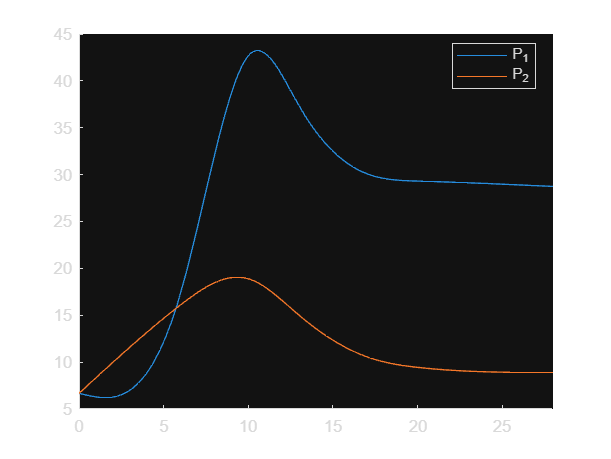


figure
hold on
fplot(P_1)
fplot(P_2)
xlim([0 28])
legend("P_1", "P_2", "location", "best")


x_sol_1 = vpasolve(diff(a_1(3) + b_1(3)*(x - 10) + c_1(3)*(x - 10)^2 + d_1(3)*(x - 10)^3) == 0, [10, 13])

$$x\_sol\_1 = 10.5534$$

x_sol_2 = vpasolve(diff(a_2(2) + b_2(2)*(x - 6) + c_2(2)*(x - 6)^2 + d_2(2)*(x - 6)^3) == 0, [6, 10])

$$x\_sol\_2 = 9.3496$$


subs(a_1(3) + b_1(3)*(x - 10) + c_1(3)*(x - 10)^2 + d_1(3)*(x - 10)^3, x, x_sol_1)

$$ans = 43.2302$$

subs(a_2(2) + b_2(2)*(x - 6) + c_2(2)*(x - 6)^2 + d_2(2)*(x - 6)^3, x, x_sol_2)

$$ans = 19.0561$$

## Problem 8 (3)

clear; clc;

syms x

x_i = [1, 1.1, 1.3, 1.5, 1.9, 2.1];
y_i = [1.84, 1.96, 2.21, 2.45, 2.94, 3.18];

syms a_0 a_1

eq1 = a_0*length(x_i) + a_1*sum(x_i) == sum(y_i);
eq2 = a_0*sum(x_i) + a_1*sum(x_i.^2) == sum(x_i.*y_i);
[a_0_sol, a_1_sol] = solve([eq1, eq2], [a_0, a_1]);
P_1(x) = a_1_sol*x + a_0_sol;
vpa(simplify(P_1), 4)

$$ans(x) = 1.2196\,x+0.6209$$


syms a_2

eq1 = a_0*length(x_i) + a_1*sum(x_i) + a_2*sum(x_i.^2) == sum(y_i);
eq2 = a_0*sum(x_i) + a_1*sum(x_i.^2) + a_2*sum(x_i.^3) == sum(x_i.*y_i);
eq3 = a_0*sum(x_i.^2) + a_1*sum(x_i.^3) + a_2*sum(x_i.^4) == sum(x_i.^2.*y_i);
[a_0_sol, a_1_sol, a_2_sol] = solve([eq1, eq2, eq3], [a_0, a_1, a_2]);
P_2(x) = a_2_sol*x^2 + a_1_sol*x + a_0_sol;
vpa(simplify(P_2), 4)

$$ans(x) = -0.0109\,x^{2}+1.2533\,x+0.5966$$


syms a_3

eq1 = a_0*length(x_i) + a_1*sum(x_i) + a_2*sum(x_i.^2) + a_3*sum(x_i.^3) == sum(y_i);
eq2 = a_0*sum(x_i) + a_1*sum(x_i.^2) + a_2*sum(x_i.^3) + a_3*sum(x_i.^4) == sum(x_i.*y_i);
eq3 = a_0*sum(x_i.^2) + a_1*sum(x_i.^3) + a_2*sum(x_i.^4) + a_3*sum(x_i.^5) == sum(x_i.^2.*y_i);
eq4 = a_0*sum(x_i.^3) + a_1*sum(x_i.^4) + a_2*sum(x_i.^5) + a_3*sum(x_i.^6) == sum(x_i.^3.*y_i);
[a_0_sol, a_1_sol, a_2_sol, a_3_sol] = solve([eq1, eq2, eq3, eq4], [a_0, a_1, a_2, a_3]);
P_3(x) = a_3_sol*x^3 + a_2_sol*x^2 + a_1_sol*x + a_0_sol;
vpa(simplify(P_3), 4)

$$ans(x) = -0.0100\,x^{3}+0.0353\,x^{2}+1.1850\,x+0.6290$$


error_1 = vpa(sum((y_i - P_1(x_i)).^2), 5)

$$error\_1 = 2.7194e-05$$

error_2 = vpa(sum((y_i - P_2(x_i)).^2), 5)

$$error\_2 = 1.8015e-05$$

error_3 = vpa(sum((y_i - P_3(x_i)).^2), 5)

$$error\_3 = 1.7407e-05$$

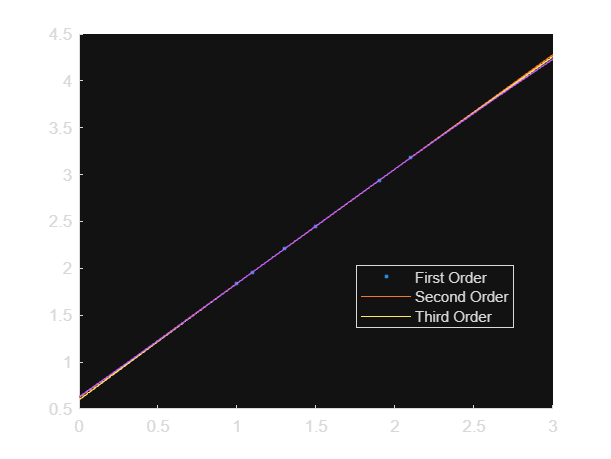


figure
hold on
plot(x_i, y_i, ".")
fplot(P_1)
fplot(P_2)
fplot(P_3)
xlim([0, 3])
legend("First Order", "Second Order", "Third Order", "Location", "best")

## Probme 9 (1b, 3b, 5b)

clear; clc;

syms x

x_int = [0, 2];
f(x) = x^3;

syms a_0 a_1
eq1 = a_0*int(1, x, x_int(1), x_int(end)) + a_1*int(x, x, x_int(1), x_int(end)) ==...
    int(f, x, x_int(1), x_int(end));
eq2 = a_0*int(x, x, x_int(1), x_int(end)) + a_1*int(x^2, x, x_int(1), x_int(end)) ==...
    int(x*f, x, x_int(1), x_int(end));
[a_0_sol, a_1_sol] = solve([eq1, eq2], [a_0, a_1]);
P_1(x) = a_1_sol*x + a_0_sol;
vpa(simplify(P_1), 4)

$$ans(x) = 3.6000\,x-1.6000$$


syms a_2
eq1 = a_0*int(1, x, x_int(1), x_int(end)) + a_1*int(x, x, x_int(1), x_int(end)) +...
    a_2*int(x^2, x, x_int(1), x_int(end)) == int(f, x, x_int(1), x_int(end));
eq2 = a_0*int(x, x, x_int(1), x_int(end)) + a_1*int(x^2, x, x_int(1), x_int(end)) +...
    a_2*int(x^3, x, x_int(1), x_int(end)) == int(f*x, x, x_int(1), x_int(end));
eq3 = a_0*int(x^2, x, x_int(1), x_int(end)) + a_1*int(x^3, x, x_int(1), x_int(end)) +...
    a_2*int(x^4, x, x_int(1), x_int(end)) == int(f*x^2, x, x_int(1), x_int(end));
[a_0_sol, a_1_sol, a_2_sol] = solve([eq1, eq2, eq3], [a_0, a_1, a_2]);
P_2(x) = a_2_sol*x^2 + a_1_sol*x + a_0_sol;
vpa(simplify(P_2), 4)

$$ans(x) = 3\,x^{2}-2.4000\,x+0.4000$$


error_1 = vpa(int((f - P_1).^2, x, x_int(1), x_int(end)), 5)

$$error\_1 = 1.6457$$

error_2 = vpa(int((f - P_2).^2, x, x_int(1), x_int(end)), 5)

$$error\_2 = 0.0457$$

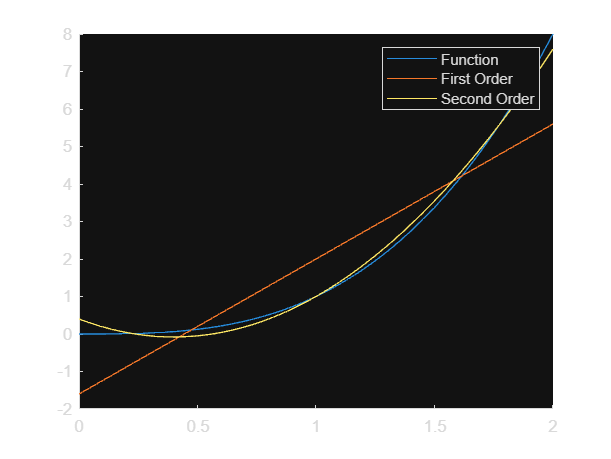


figure
hold on
fplot(f)
fplot(P_1)
fplot(P_2)
xlim([x_int(1), x_int(end)])
legend("Function", "First Order", "Second Order")

## Problem 10 (2a)

clear; clc;

syms x

f(x) = exp(x);

x_vec = [-1, 1, 0, sqrt(2)/2, -sqrt(2)/2, sqrt(3)/2, -sqrt(3)/2, sqrt(2 + sqrt(2))/2, sqrt(2 - sqrt(2))/2, -sqrt(2 + sqrt(2))/2, -sqrt(2 - sqrt(2))/2]';
x_vec = sort(x_vec);
f_vec = f(x_vec);
f_diff_vec = f_vec;

P_Lagrange = LagrangePolynomial(f_vec, x_vec);
vpa(expand(P_Lagrange), 4)

$$ans = 2.8376e-07\,x^{10}+2.8390e-06\,x^{9}+2.4794e-05\,x^{8}+1.9831e-04\,x^{7}+0.0014\,x^{6}+0.0083\,x^{5}+0.0417\,x^{4}+0.1667\,x^{3}+0.5000\,x^{2}+1.0000\,x+1$$


F = sym(HermiteMethod(f_diff_vec, f_vec, x_vec));
P_Hermite(x) = F(1, 2);
for i = 2:length(F)-1
    G(x) = x/x;
    for j = 1:i-1
        G(x) = G(x)*(x - F(j,1));
    end
    P_Hermite(x) = P_Hermite(x) + F(i, i+1)*G(x);
end
vpa(expand(P_Hermite), 4)

$$ans(x) = -1.0265e-11\,x^{21}-4.0858e-11\,x^{20}+5.8513e-11\,x^{19}+2.3250e-10\,x^{18}-1.4328e-10\,x^{17}-5.6961e-10\,x^{16}+1.9763e-10\,x^{15}+7.9635e-10\,x^{14}-5.6158e-12\,x^{13}+1.4217e-09\,x^{12}+2.5141e-08\,x^{11}+2.7593e-07\,x^{10}+2.7557e-06\,x^{9}+2.4801e-05\,x^{8}+1.9841e-04\,x^{7}+0.0014\,x^{6}+0.0083\,x^{5}+0.0417\,x^{4}+0.1667\,x^{3}+0.5000\,x^{2}+1\,x+1$$


[a, b, c, d] = naturalSpline(f_vec, x_vec);
funcs = cell(1, length(x_vec)-1);
for i = 1:length(x_vec)-1
    poly(x) = a(i) + b(i)*(x - x_vec(i)) + c(i)*(x - x_vec(i))^2 + d(i)*(x - x_vec(i))^3;
    funcs{i} = poly(x);
end
P_Spline = piecewise(x >= x_vec(1) & x <= x_vec(2), funcs{1},...
    x >= x_vec(2) & x <= x_vec(3), funcs{2},...
    x >= x_vec(3) & x <= x_vec(4), funcs{3},...
    x >= x_vec(4) & x <= x_vec(5), funcs{4},...
    x >= x_vec(5) & x <= x_vec(6), funcs{5},...
    x >= x_vec(6) & x <= x_vec(7), funcs{6},...
    x >= x_vec(7) & x <= x_vec(8), funcs{7},...
    x >= x_vec(8) & x <= x_vec(9), funcs{8},...
    x >= x_vec(9) & x <= x_vec(10), funcs{9},...
    x >= x_vec(10) & x <= x_vec(11), funcs{10});
vpa(expand(P_Spline), 4)

$$ans = \left\{ \begin{array}{cl} 1.1048\,x^{3}+3.3144\,x^{2}+3.6902\,x+1.8485 & \text{ if }x\in \left[-1,-0.9239\right]\\ -0.2862\,x^{3}-0.5411\,x^{2}+0.1282\,x+0.7516 & \text{ if }x\in \left[-0.9239,-0.8660\right]\\ 0.0920\,x^{3}+0.4416\,x^{2}+0.9793\,x+0.9972 & \text{ if }x\in \left[-0.8660,-0.7071\right]\\ 0.0927\,x^{3}+0.4432\,x^{2}+0.9804\,x+0.9975 & \text{ if }x\in \left[-0.7071,-0.3827\right]\\ 0.1374\,x^{3}+0.4944\,x^{2}+0.9999\,x+1 & \text{ if }x\in \left[-0.3827,0\right]\\ 0.1986\,x^{3}+0.4944\,x^{2}+0.9999\,x+1 & \text{ if }x\in \left[0,0.3827\right]\\ 0.3039\,x^{3}+0.3735\,x^{2}+1.0463\,x+0.9941 & \text{ if }x\in \left[0.3827,0.7071\right]\\ 0.2375\,x^{3}+0.5145\,x^{2}+0.9466\,x+1.0176 & \text{ if }x\in \left[0.7071,0.8660\right]\\ 3.0295\,x^{3}-6.7396\,x^{2}+7.2287\,x-0.7959 & \text{ if }x\in \left[0.8660,0.9239\right]\\ -7.2571\,x^{3}+21.7714\,x^{2}-19.1119\,x+7.3160 & \text{ if }x\in \left[0.9239,1\right] \end{array}\right.$$


Lagrange_int = int(P_Lagrange, x, -1, 1);
Hermite_int = int(P_Hermite, x, -1, 1);
Spline_int = int(P_Spline, x, -1, 1);
Actual_int = int(f, x, -1, 1);

vpa(Lagrange_int, 16)

$$ans = 2.3504$$

vpa(Hermite_int, 16)

$$ans = 2.3504$$

vpa(Spline_int, 16)

$$ans = 2.3504$$

vpa(Actual_int, 16)

$$ans = 2.3504$$


rel_err_L = abs(Actual_int - Lagrange_int)

$$rel\_err\_L = 8.6541e-14$$

rel_err_H = abs(Actual_int - Hermite_int)

$$rel\_err\_H = 7.6395e-16$$

rel_err_S = abs(Actual_int - Hermite_int)

$$rel\_err\_S = 7.6395e-16$$